clear variables

load('lab8_1.mat')

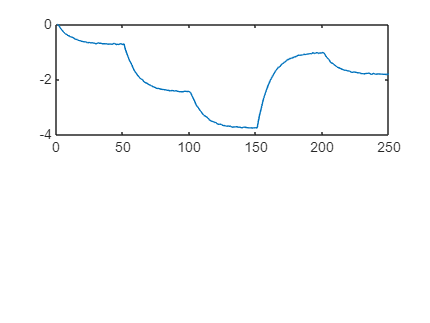


yid = id.y;
uid = id.u;
yval = val.y;
uval = val.u;
Ts = val.Ts;

figure,
subplot(211)
plot(yval)
hold on


% Stepsize
alpha = 0.5;
% Threshold
gama = 1e-4;
% Iteration range
lmax = 250;
% Initial parameter vector
theta = [1;1];
f = theta(1);
b = theta(2);
N = length(transpose(yid));

l = 1;

## Computing recursion formulas and applying them to find Epsilon(k)

Epsilon_derivated = zeros(2,N);
Epsilon = zeros(1,N);
for k = 2 : 1 : N
    Epsilon_derivated(1,k) = yid(k-1) - f*Epsilon_derivated(1,(k-1)) - Epsilon(k-1);
    Epsilon_derivated(2,k) = -uid(k-1) - f*Epsilon_derivated(2,(k-1));
end

Epsilon_derivated_recursive = zeros(2,N);

## Repeat the steps below

until l reaches lmax or the norm between 2 consecutives theta terms is greater than gamma

while ((l < lmax) || (norm(theta(:,l) - theta(:,(l-1))) > gama))
   
    for k = 2 : 1 : N
        Epsilon(k) = yid(k) + theta(1,l)*yid(k-1) - theta(2,l)*uid(k-1) - f*Epsilon(k-1);
        Epsilon_derivated_recursive(1,k) = yid(k-1) - theta(1,l)*Epsilon_derivated_recursive(1,(k-1)) - Epsilon(k-1);
        Epsilon_derivated_recursive(2,k) = -uid(k-1) - theta(1,l)*Epsilon_derivated_recursive(2,(k-1));
    end
    % Compute gradient of the objective function
    gradient_sum = 0;
    for k = 1 : 1 : N
        gradient_sum = gradient_sum + Epsilon(:,k)*Epsilon_derivated_recursive(:,k);
    end
    dV_dtheta = 2*gradient_sum / N;   
    % Compute approximate Hessian of the objective function
    hessian_sum = 0;
    for k = 1 : 1 : N
        hessian_sum = hessian_sum + Epsilon_derivated_recursive(:,k)*transpose(Epsilon_derivated_recursive(:,k));
    end
    H = 2*hessian_sum / N;
    % Apply Gauss-Newton update formula
    theta(:,(l+1)) = theta(:,l) - alpha*inv(H)*dV_dtheta;
    % Increment the counter
    l = l+1;

end

## Plot the results

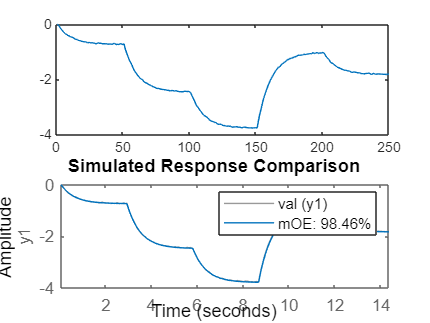

subplot(212)
mOE = idpoly(1,[0 theta(2,end)],1,1,[1 theta(1,end)],0,Ts);
compare(val,mOE)
hold off